musicname="data\599-60.wav";
jpegname="data\599-60.jpg";
musicJname="data\599-60-J.wav";

[matrix2D,fs]=music2jpeg(musicname,jpegname);
music_J=jpeg2music(jpegname,musicJname,fs);

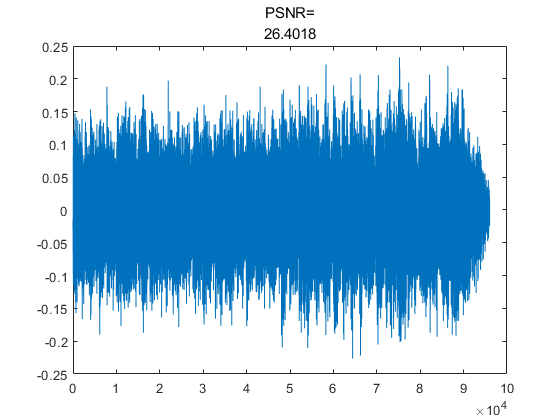

[music,~]=audioread(musicname);
music=music';
music=music/(max(music)-min(music))*2; % normalization
music_J(length(music)+1:end)=[]; % cut mute part

plot([0:length(music)-1],music_J-music);
MSE=sum((music-music_J).^2,"all")/numel(music);
PSNR=10*log10(1^2/MSE);
title("PSNR=",num2str(PSNR));

secret="Hello World, and by the way, BirdX is watching you.";
hideInJpeg_DCTall(secret,"data/hall.jpg","data/hide1.jpg");
secret1=findInJpeg_DCTall("data/hide1.jpg");
disp(secret1);

Hello World, and by the way, BirdX is watching you.


hideInJpeg_DCTascend(secret,"data/hall.jpg","data/hide2.jpg");
secret2=findInJpeg_DCTascend("data/hide2.jpg");
disp(secret2);

Hello World, and by the way, BirdX is watching you.
